figure
%原始数据

x= [-0.1293 -0.2498 -0.3623 -0.4676 -0.5665 -0.6593 -0.7468 -0.8293 -0.9073 -0.9811]

x =    -0.1293   -0.2498   -0.3623   -0.4676   -0.5665   -0.6593   -0.7468   -0.8293   -0.9073   -0.9811


VRt = [2093 1378 0884 0583 0404 0280 0200 0144 0106 0079]

VRt =         2093        1378         884         583         404         280         200         144         106          79


vr = repmat(0.9974, 1, 10);
Rt = VRt./ vr

Rt = 1.0e+03 *

    2.0985    1.3816    0.8863    0.5845    0.4051    0.2807    0.2005    0.1444    0.1063    0.0792



y=log(Rt)

y =     7.6490    7.2310    6.7871    6.3708    6.0040    5.6374    5.3009    4.9724    4.6660    4.3721


a=polyfit(x,y,1)

a =     3.8657    8.1796


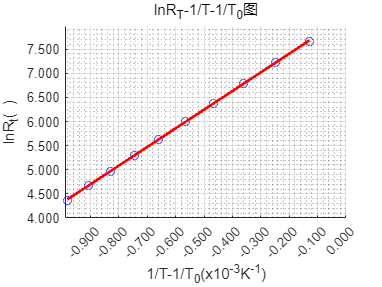

% 创建一些示例数据


% 选择多项式的阶数，例如一次多项式（线性拟合）
degree = 1;

% 进行多项式拟合
coefficients = polyfit(x, y, degree);

% 生成拟合的曲线
fit_curve = polyval(coefficients, x);

% 绘制原始数据和拟合曲线
figure;
scatter(x, y, 'b');  % 散点图
hold on;
plot(x, fit_curve, 'r', 'LineWidth', 2);  % 拟合曲线
title("lnR_{T}-1/T-1/T_{0}图")
ylabel('lnR_{t}( )')

xlim([-0.99 0.00])
ylim([4.00 7.98])
xlabel("1/T-1/T_{0}(x10^{-3}K^{-1})")
xticks(-1:0.1:0)
xtickformat('%.3f')
ytickformat('%.3f');
grid on
grid minor
hold off;



a=polyfit(x,y,1)

a =     3.8657    8.1796


yi = polyval(a,x)

yi =     7.6797    7.2139    6.7790    6.3720    5.9896    5.6309    5.2927    4.9737    4.6722    4.3869


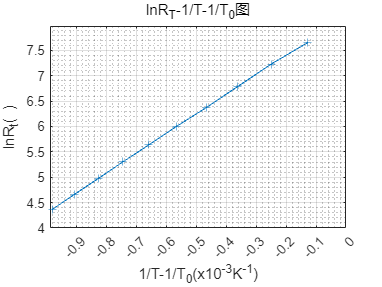

plot(x,y,Marker='+')
ylabel('lnR_{t}( )')

xlim([-0.99 0.00])
ylim([4.00 7.98])
xlabel("1/T-1/T_{0}(x10^{-3}K^{-1})")
xticks(-1:0.1:0)

grid on
grid minor

title("lnR_{T}-1/T-1/T_{0}图")

% 使用polyfit进行线性拟合，阶数为1

% 生成新的数据点
xi = 0:10:100;
yi = polyval(a,xi)

yi =     8.1796   46.8366   85.4937  124.1508  162.8079  201.4650  240.1221  278.7792  317.4362  356.0933  394.7504


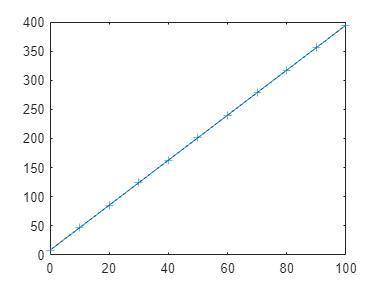

%绘图
plot(xi,yi,Marker="+");



% 计算相关系数矩阵
corr_matrix = corrcoef(x, y);

% 获取相关系数（Pearson相关系数）
correlation_coefficient = corr_matrix(1, 2);

% 计算R方值
r_squared = correlation_coefficient^2;

disp(['相关系数 (r)：', num2str(correlation_coefficient)]);

相关系数 (r)：0.99991


disp(['R方值 (r^2)：', num2str(r_squared)]);

R方值 (r^2)：0.99983
